Individual Assignment #1

First step: Load the sung wav file and make spectrums of it.

Vi prøver nu at plotte dem sammen i det samme plot.

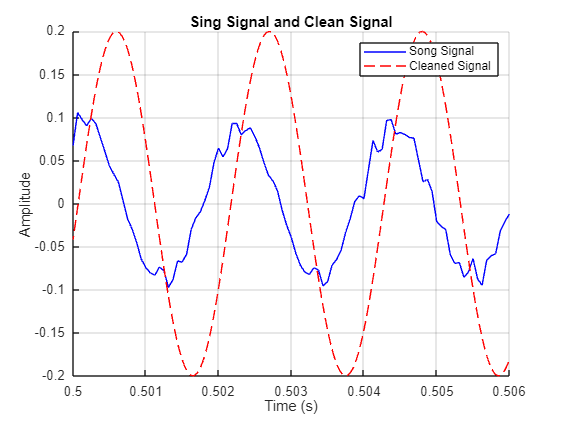

path_2_wav = ['C:\Users\45422\Desktop\DSP\', filesep, 'Sounds', filesep];    % the path to the data
fname = 'iii.wav';                                 % a file name stored in a string variable
[sing_signal, fs_sing] = audioread([path_2_wav,fname]); % Load the audio file and extract the sampling frequency

% Compute the Fourier Transform
Y_sing = fft(sing_signal);
n_sing = length(sing_signal);
f_sing = (0:n_sing-1) * (fs_sing / n_sing); % Frequency vector

% Compute the magnitude in dB
magnitude_dB_sing = 20 * log10(abs(Y_sing) / max(abs(Y_sing)));


% Create a synthetic signal with a fundamental frequency around 1000 Hz
fundamental_freq = 475.6;

% Parameters
fs = 44100;  % Sampling frequency (samples per second)
f = 500;     % Frequency of the sine wave (Hz)
T = 1;       % Duration of the signal (seconds)
t = 0:1/fs:T-1/fs; % Time vector

noise_level = 0.2;

% Generate 500 Hz sine wave
clean_signal =noise_level* sin(2 * pi * fundamental_freq * t+pi/3);

Y = fft(signal);
n = length(signal);
f=(0:n-1)*(fs/n);

%----
t_sing = (0:length(sing_signal)-1) / fs_sing; % Time vector
t_clean = (0:length(clean_signal)-1) / fs;
figure;
hold on;
plot(t_sing, sing_signal, 'b','DisplayName','Song Signal');
plot(t_clean, clean_signal, 'r--', 'DisplayName','Cleaned Signal');
xlabel('Time (s)');
ylabel('Amplitude');
title('Sing Signal and Clean Signal');
xlim([0.5 0.506]); % Limit the x-axis to 0 to 1 second
ylim([-0.2, 0.2]);
legend('show');
grid on; 
hold off;

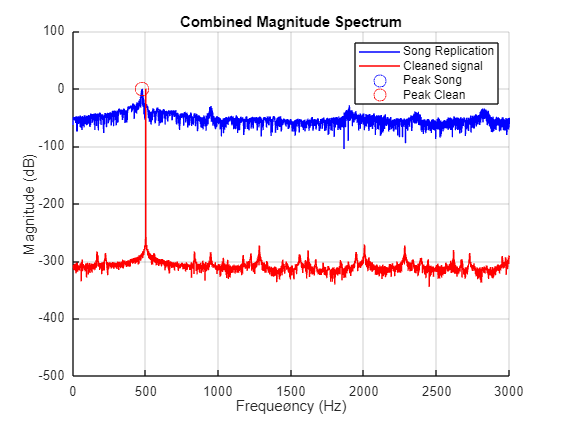


figure;
hold on;
plot(f_sing(1:floor(n_sing/2)+1), magnitude_dB_sing(1:floor(n_sing/2)+1), 'b', 'DisplayName', 'Song Replication');
plot(f(1:floor(n/2)+1), magnitude_db(1:floor(n/2)+1), 'r--', 'DisplayName', 'Cleaned signal','LineStyle','-');
xlabel('Frequeøncy (Hz)');
ylabel('Magnitude (dB)');
title('Combined Magnitude Spectrum');
xlim([0 3000]);
ylim([-500 100]);
grid on;

% Highlight the peaks
[~, peakIndex1] = max(magnitude_dB_sing(1:floor(n_sing/2)+1));
peakFreq1 = f_sing(peakIndex1);
[~, peakIndex2] = max(magnitude_dB_clean);
peakFreq2 = f_clean(peakIndex2);
plot(peakFreq1, magnitude_dB_sing(peakIndex1), 'bo', 'MarkerSize', 10, 'DisplayName', 'Peak Song');
plot(peakFreq2, magnitude_dB_clean(peakIndex2), 'ro', 'MarkerSize', 10, 'DisplayName', 'Peak Clean');

legend('show');
hold off;